# Time evolution for a DAE system on a star graph

Evolves the basic heat equation through time.

## Set up the graph structure and coordinates of the problem

By default, the discretization type is uniform but you must choose it to be Chebyshev for the time evolution. You can also set other properties such as the number of discretization points per edge.

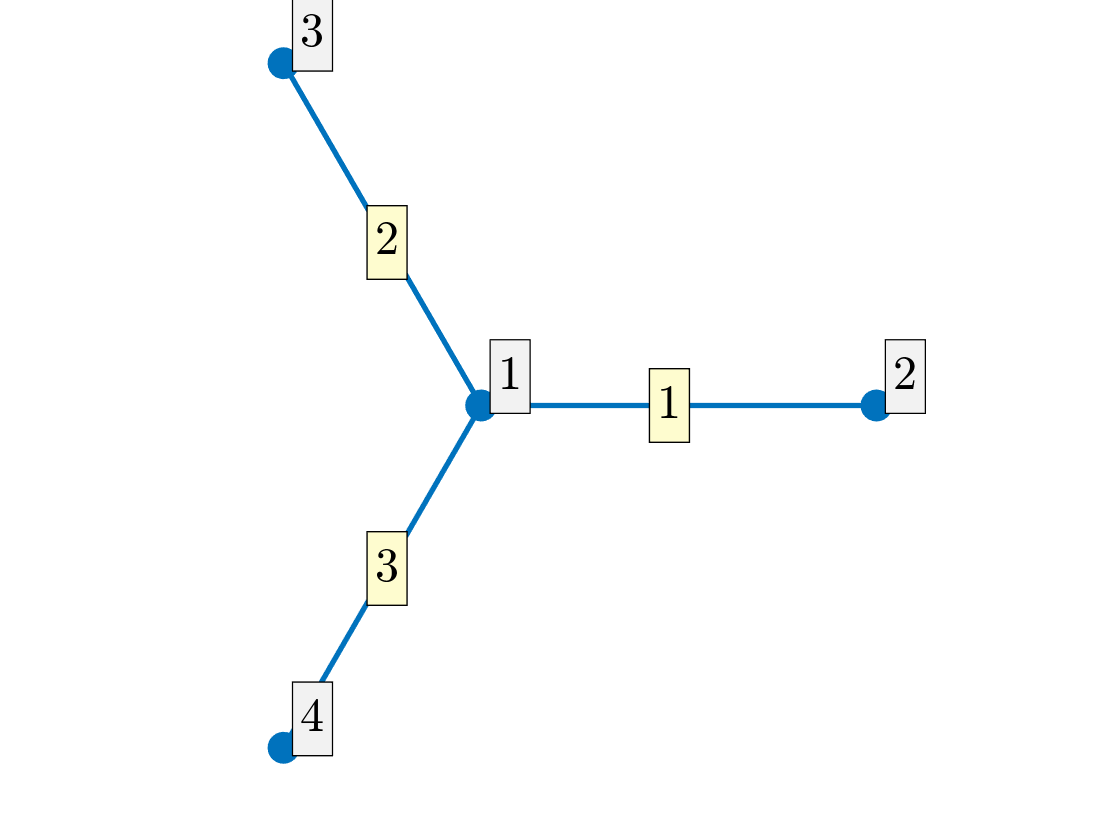

Phi = quantumGraphFromTemplate('star','discretization','Chebyshev','nX',32);
Phi.plot('layout')

## Define the function

1 = heat

2 = Schrodinger

3 = NLS

type = 2;
f = Phi.myFunc(type);

## Time evolution

You need an initial condition, step size, how long the program should run till and the scheme type you desire. Right now, we have 2nd, 4th and 8th order schemes. For this example, I put a soliton on one of the edges of the star graph and propogated it towards the junction.

xgrid = pi*chebptsSecondKind(32)';
f0 = [-exp(1i*xgrid)+1 zeros(1,68)]';
tend = 1;
[u,t] = Phi.timeEvolveDAEDopri8(f,f0,1e-04,tend,8);

## Plotting the solution

Plotting every piece of information is too much. We'll only plot every 100th data point.

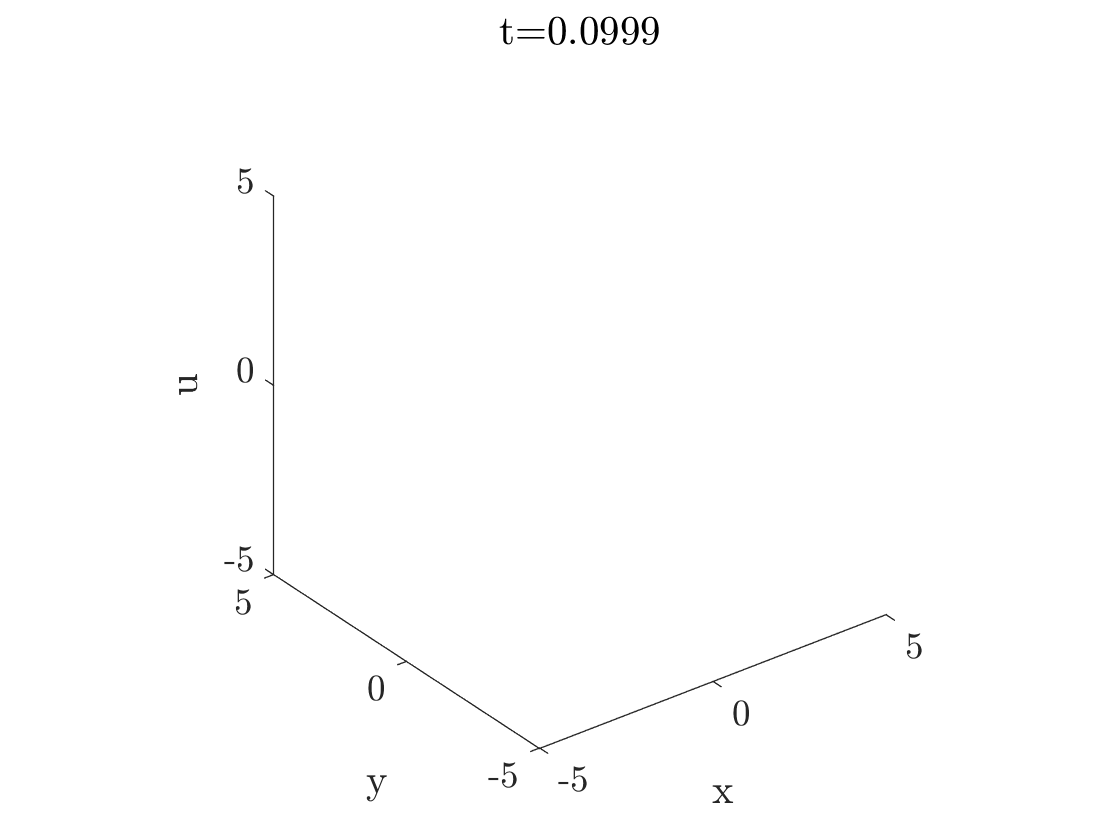

scale = 100;
for i=1:10 %size(u,2)/scale
    if type == 1
        Phi.plot(u(:,scale*i))
    else
        Phi.plot(abs(u(:,i)))%scale*i)).^2)
    end
    title(['t=',num2str( t(scale*i) )])
    axis([-5 5 -5 5 -5 5])
    daspect([1 1 1])
    xlabel('x')
    ylabel('y')
    zlabel('u')
    pause(.0000000000001)
end

## Error Analysis

We use an analytical solution to 

if type == 1
    uana = @(t) exp(-lambda*t).*u0;
else
    uana = @(t) exp(-1i*lambda*t).*u0;
end
error = zeros(1,size(u,2));

for i=1:size(u,2)/scale
    error(scale*i) = max(uana(t(scale*i)) - u(:,scale*i));
end

disp('The error is:')

The error is:


disp(abs(max(error)))

     0

